# s_oeBloodFluorophoreTongueSrch700 

## Initialize

Different analyses are based on different wavebands.

ieInit;
wave = 510:700;
normWave = 520;
yscale = 'linear';
odLevels = 1:1:50;
[T,dataDir] = oeDatabaseCreate;

## Create fluorophore matrix and read database 

**Our winners so far**

- fluorophoreNames = 

- {'collagen1-smooth','KeratinWuQu','FADWuQu','PorphyrinBjurshammar','chlorophyllA-7'}

We should also try deoxygenated blood at some point, by adding in a collagen-deoxy column.

fluorophoreNamesB = ...
    {'collagen1-smooth','KeratinWuQu','FADWuQu','PorphyrinBjurshammar','chlorophyllA-7'};
[fluorophoresB,wave] = fiLoadBasis(fluorophoreNamesB,'wave',wave);

## 405/415 nm excitation

subjects = {'Z','B','D','J'};

% Here is oxy
% https://omlc.org/spectra/hemoglobin/summary.html
oxyblood = medium('oxy_molarExtinctionCoefficient.mat','wave',wave);
odError = zeros(numel(odLevels),numel(subjects));  
ods = zeros(numel(subjects),1);    
rmse = zeros(size(subjects));

for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',405,'e level',980);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',415,'e level',910);
    tongueFiles = cat(1,files405,files415);

    tongueData = oeReadFiles(tongueFiles,'normalized wave',normWave,'wave',wave);    
    [ods(ii),odError(:,ii)] = oeBloodEstimateOD(fluorophoresB,fluorophoreNamesB,tongueData,wave,odLevels);
end
fprintf('OD across subjects for 405/415nm %.2f\n',ods);

OD across subjects for 405/415nm 19.00
OD across subjects for 405/415nm 19.00
OD across subjects for 405/415nm 17.00
OD across subjects for 405/415nm 21.00


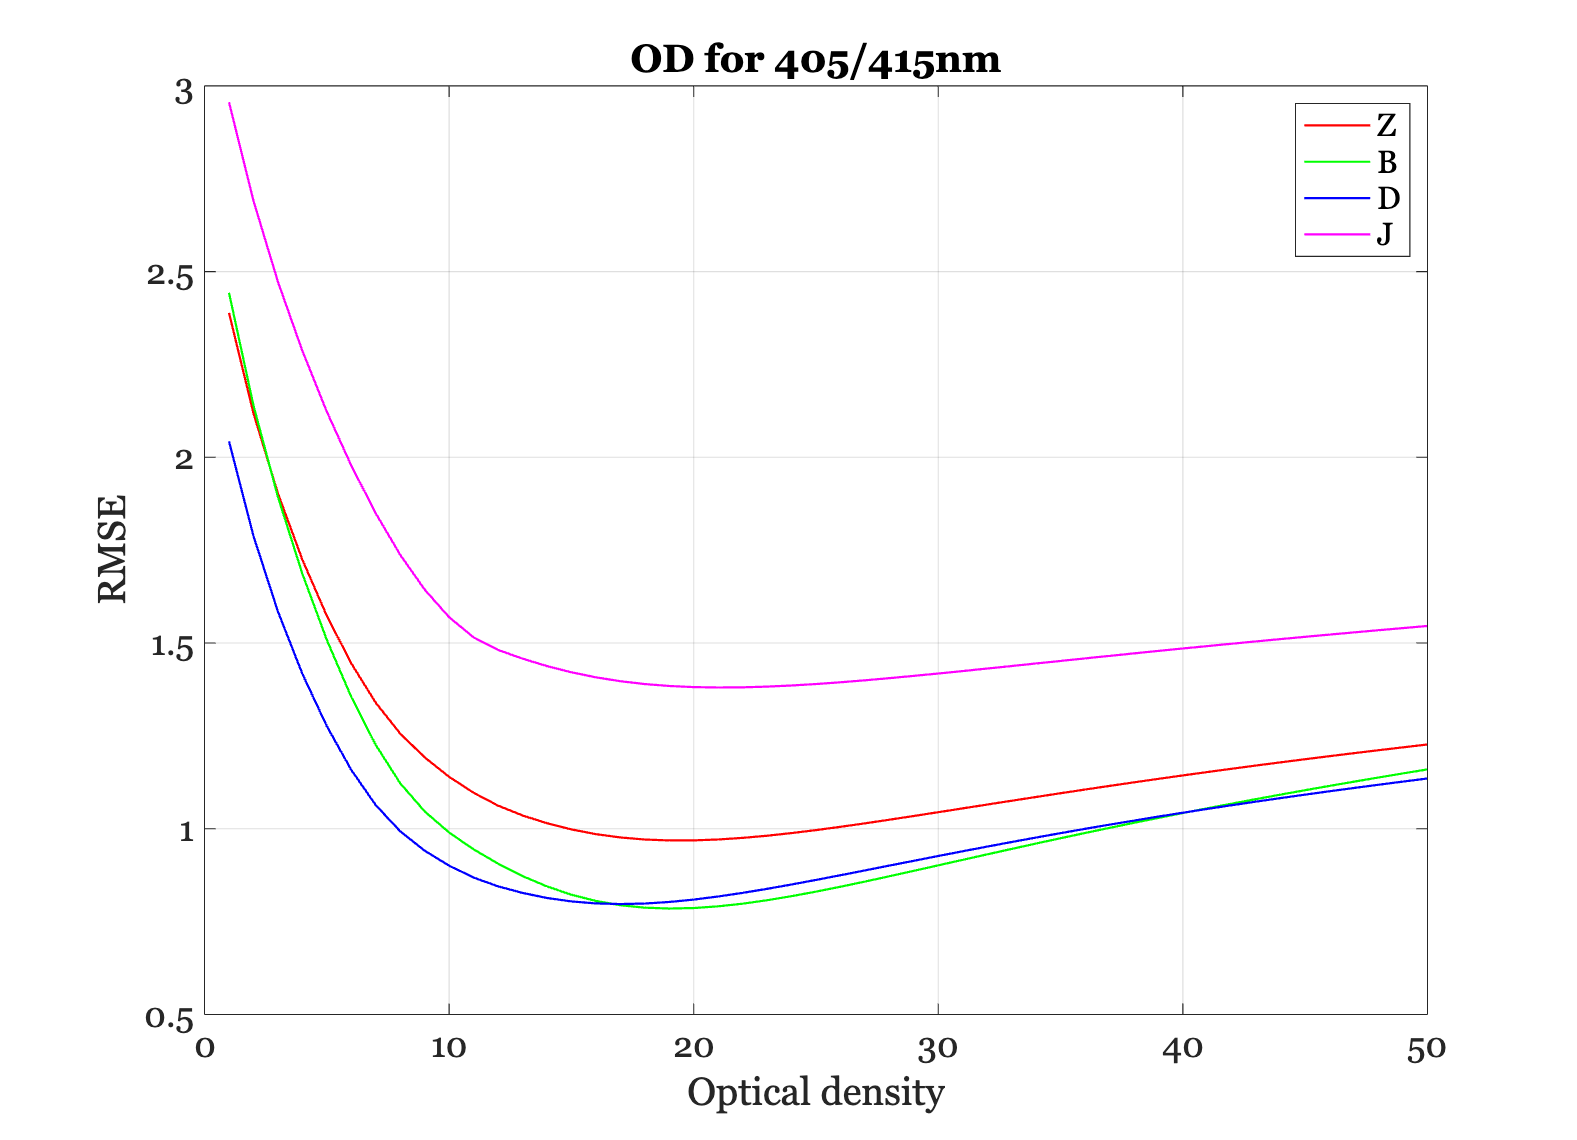


% These are the optical density levels to use for each of the subjects
ieFigure;
plot(odLevels,odError); hold on;
grid on; title('OD for 405/415nm');
legend(subjects);
xlabel('Optical density'); ylabel('RMSE');

## Apply the proper optical density and plot

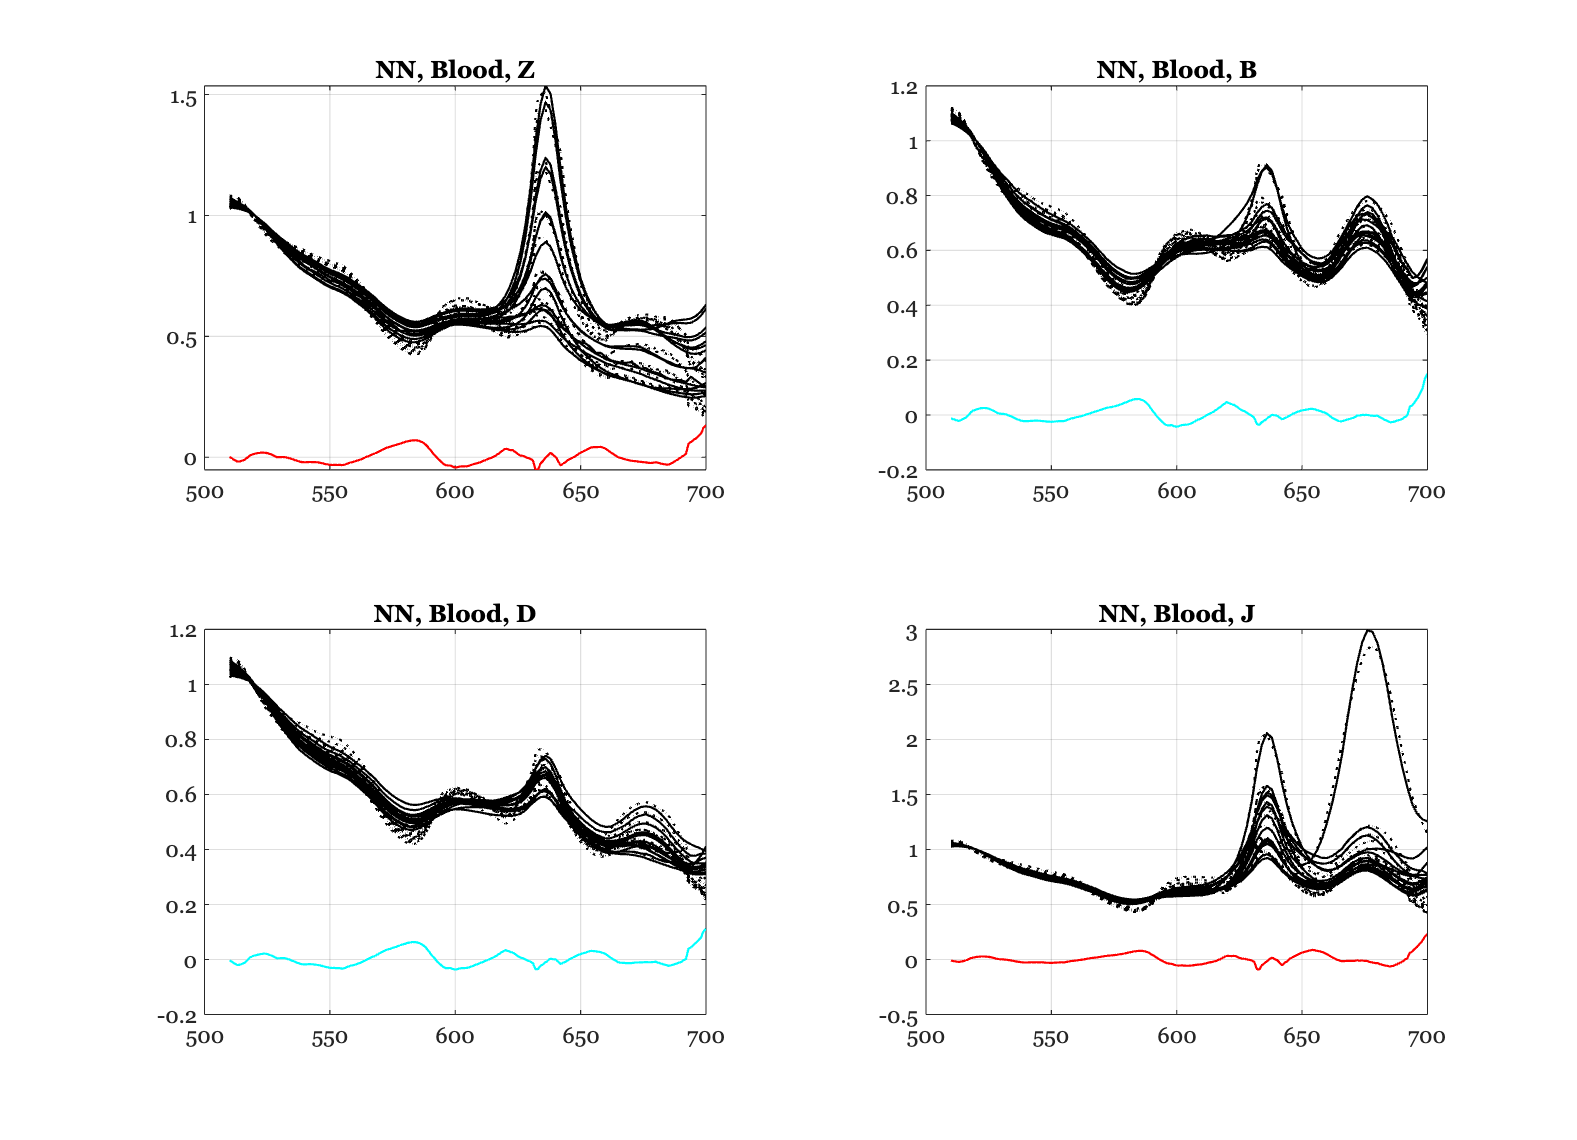

Subject Z
   13.3077   13.7066   13.9058   13.3051   14.7335   13.9271   14.6879   13.7339   13.7903   13.4100   15.2548   13.4805   11.7984   11.9809   11.9946
    1.6127    1.4860    1.3457    1.7396    0.8606    1.1263    0.8604    1.3054    1.0751    1.1474    0.9061    1.7945    1.4662    1.4402    1.4354
    0.5531    0.5804    0.6132    0.5204    0.7180    0.6622    0.7189    0.6212    0.6785    0.6640    0.6995    0.5029    0.6051    0.6083    0.6089
    0.1985    0.1744    0.2970    0.1325    0.7032    0.7574    0.5246    0.5571    1.0475    0.9859    0.4098    0.3171    0.1941    0.2782    0.1252
    0.0757    0.0823    0.1375    0.0587    0.1728    0.2031    0.2132    0.2337    0.1754    0.2015    0.2255    0.1529    0.0316    0.0237    0.0339

Subject B
   16.7753   15.9894   16.1942   17.8202   16.6673   16.5273   15.6379   17.3733   16.3463   16.3503   15.4507   15.1800   14.3355   15.3808
    1.5844    1.2553    1.3799    1.8116    1.7962    1.9141    1.9746    1.7888   

ieFigure;
tiledlayout(2,2);

deoxyblood = medium('deoxy_molarExtinctionCoefficient.mat','wave',wave);
deoxyblood.opticalDensity = 5;

for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',405);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',415);
    tongueFiles = cat(1,files405,files415);
    tongueData = oeReadFiles(tongueFiles,'normalized wave',normWave,'wave',wave);

    oxyblood.opticalDensity = ods(ii);
    [fluorophores, fluorophoreNames]  = oeApplyBlood(fluorophoresB,fluorophoreNamesB,...
        oxyblood);
    wgtsNN = zeros(size(fluorophores,2),size(tongueData,2));

    for dd = 1:size(tongueData,2)
        wgtsNN(:,dd) = lsqnonneg(fluorophores,tongueData(:,dd));
    end
    residual = tongueData - fluorophores*wgtsNN;
    rmse(ii) = norm(residual(:),2);

    nexttile
    plot(wave,tongueData,'k-',wave,fluorophores*wgtsNN,'k:', ...
        wave,mean(residual,2));
    grid on; title(sprintf('NN, Blood, %s',subjects{ii}));
    fprintf('Subject %s\n',subjects{ii}); disp(wgtsNN);
end

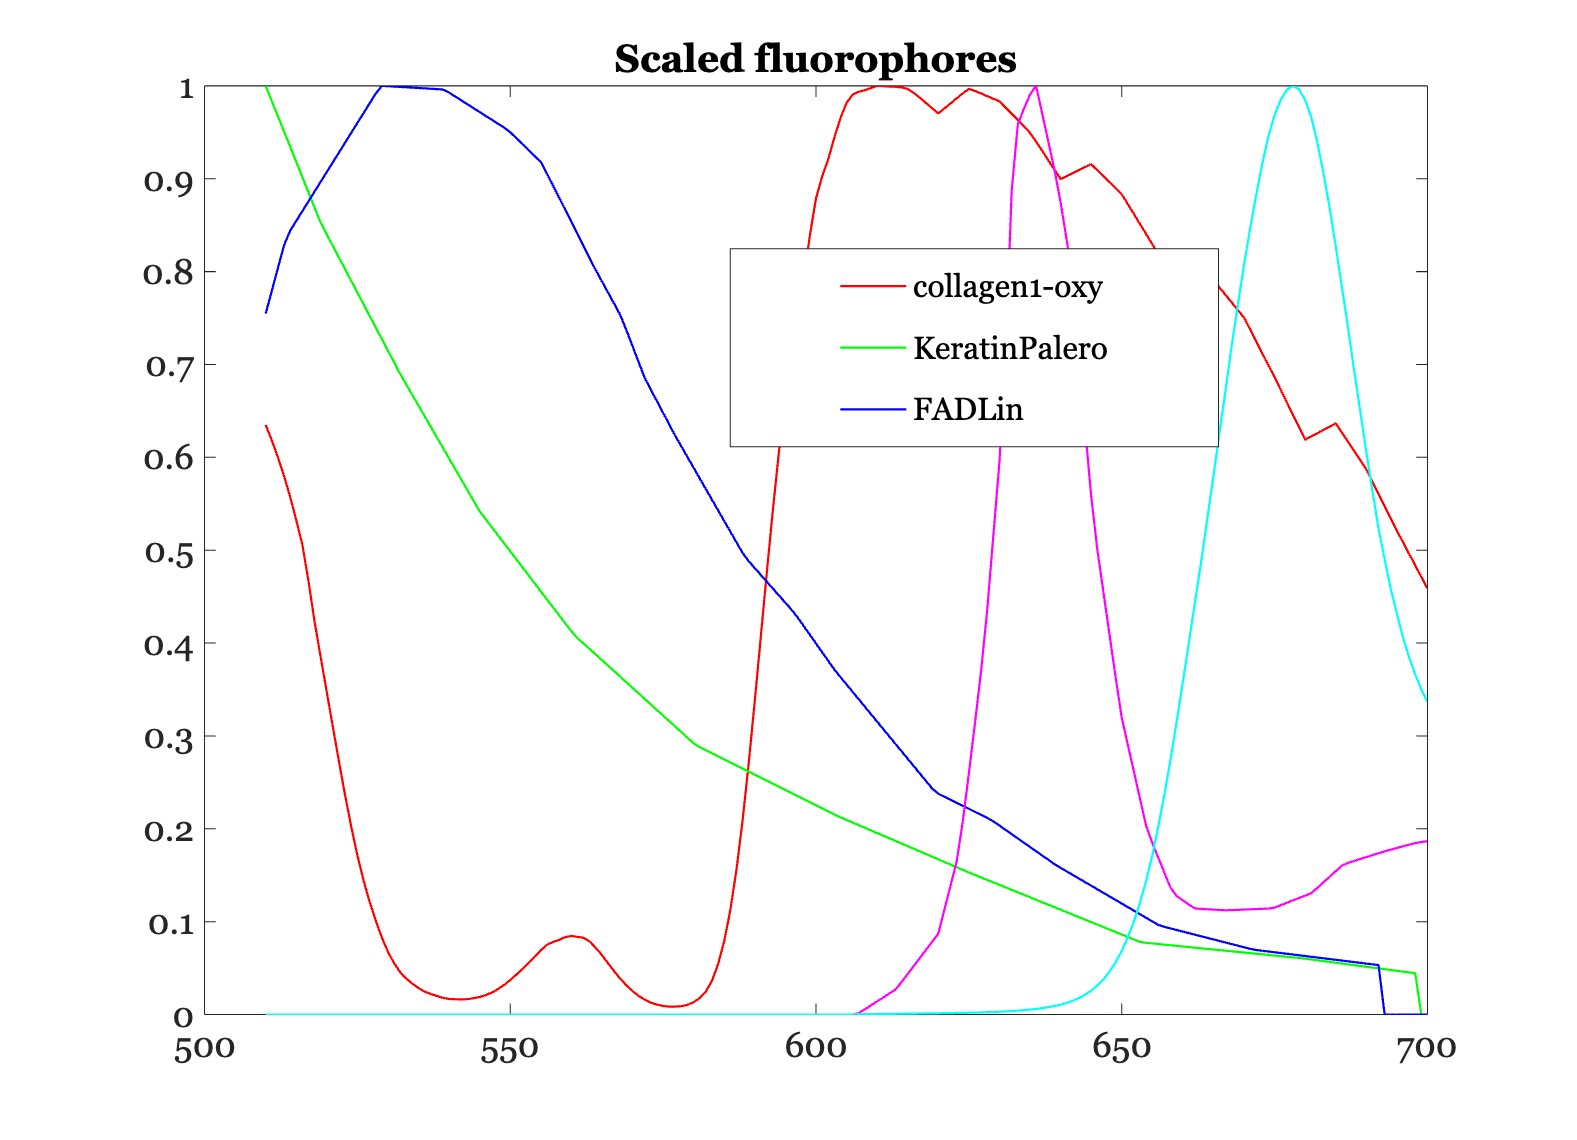


ieFigure; 
mx = max(fluorophores);
plot(wave,fluorophores*diag(1./mx));
title('Scaled fluorophores');
legend(fluorophoreNames);

legend(["collagen1-oxy", "KeratinPalero", "FADLin"], "Position", [0.4630 0.6080 0.3095, 0.1743])


disp(rmse); 

    1.8873    1.5965    1.4915    2.8401



## Create 450 nm blood optical density levels

odError = zeros(numel(odLevels),numel(subjects));

for ii=1:numel(subjects)
    files450 = ieTableGet(T,'subject',subjects{ii},...
        'substrate','tongue',...
        'e wave',450);
    tongueData = oeReadFiles(files450,'normalized wave',normWave,'wave',wave);
    [ods(ii),odError(:,ii)] = oeBloodEstimateOD(fluorophoresB,fluorophoreNamesB,tongueData,wave,odLevels);
end
fprintf('OD across subjects for 405/415nm %.2f\n',ods);

OD across subjects for 405/415nm 17.00
OD across subjects for 405/415nm 19.00
OD across subjects for 405/415nm 17.00
OD across subjects for 405/415nm 17.00


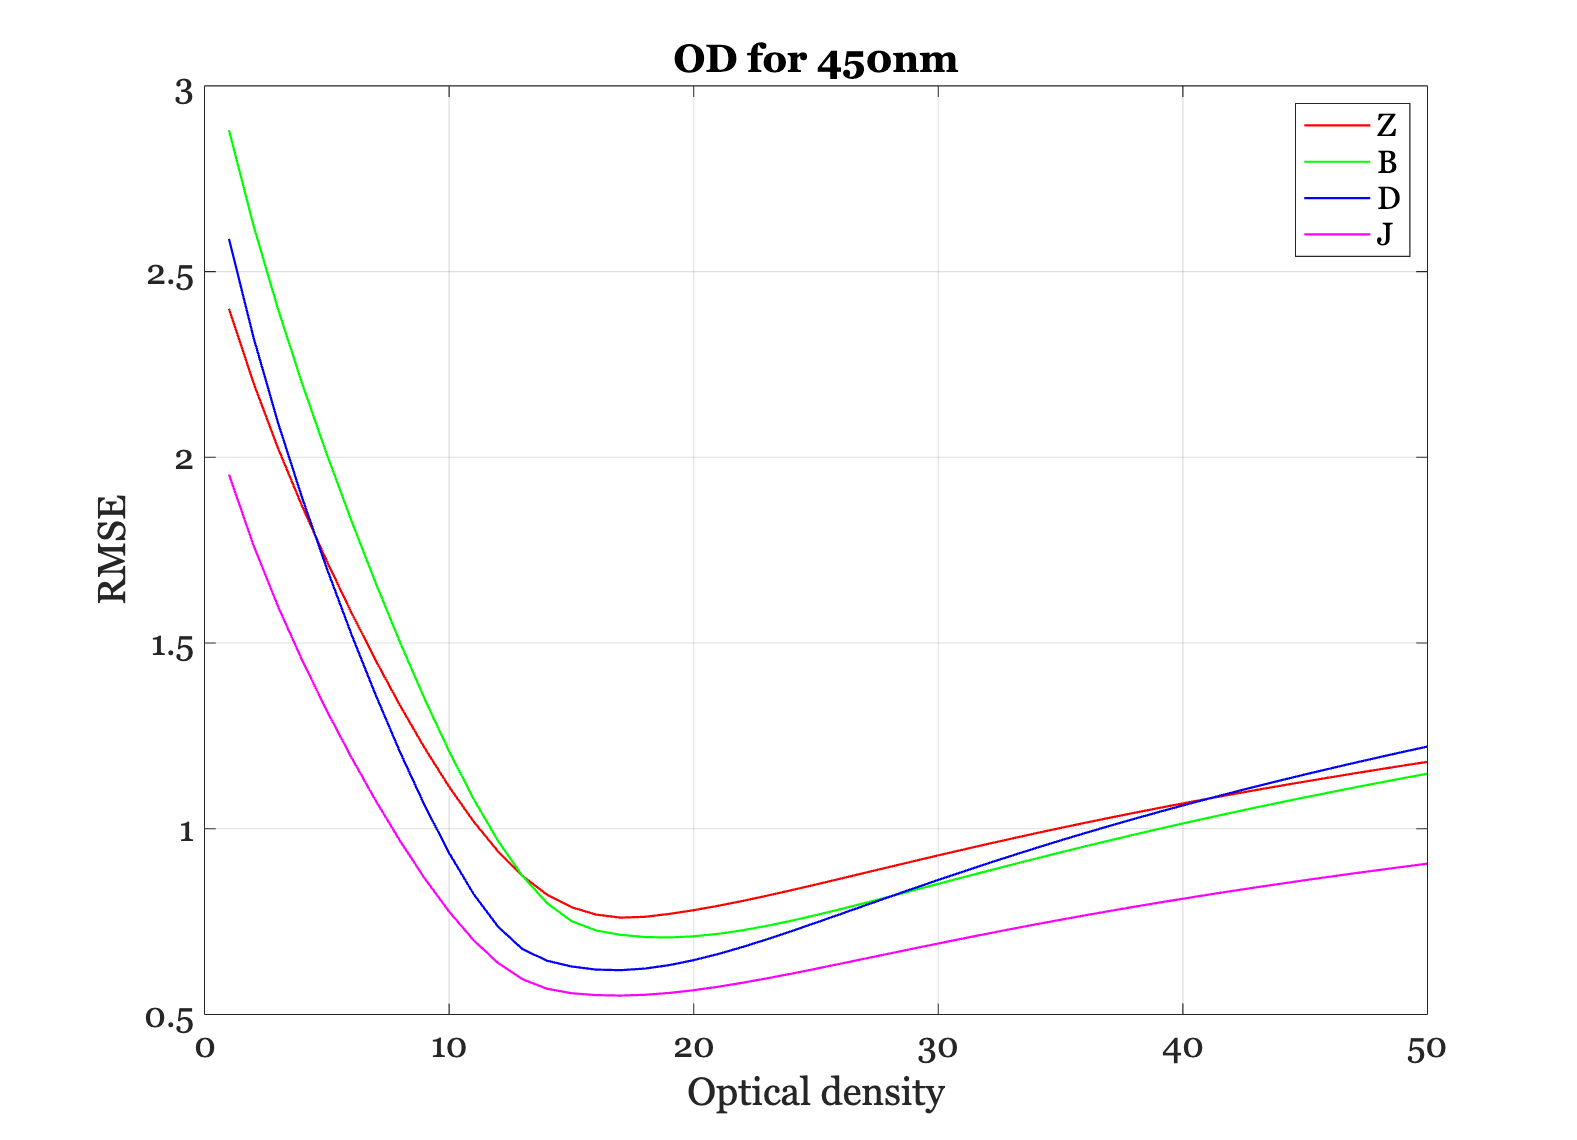



% These are the optical density levels to use for each of the subjects
ieFigure;
plot(odLevels,odError); hold on;
grid on; title('OD for 450nm');
legend(subjects);
xlabel('Optical density'); ylabel('RMSE');

## 450 nm excitation light

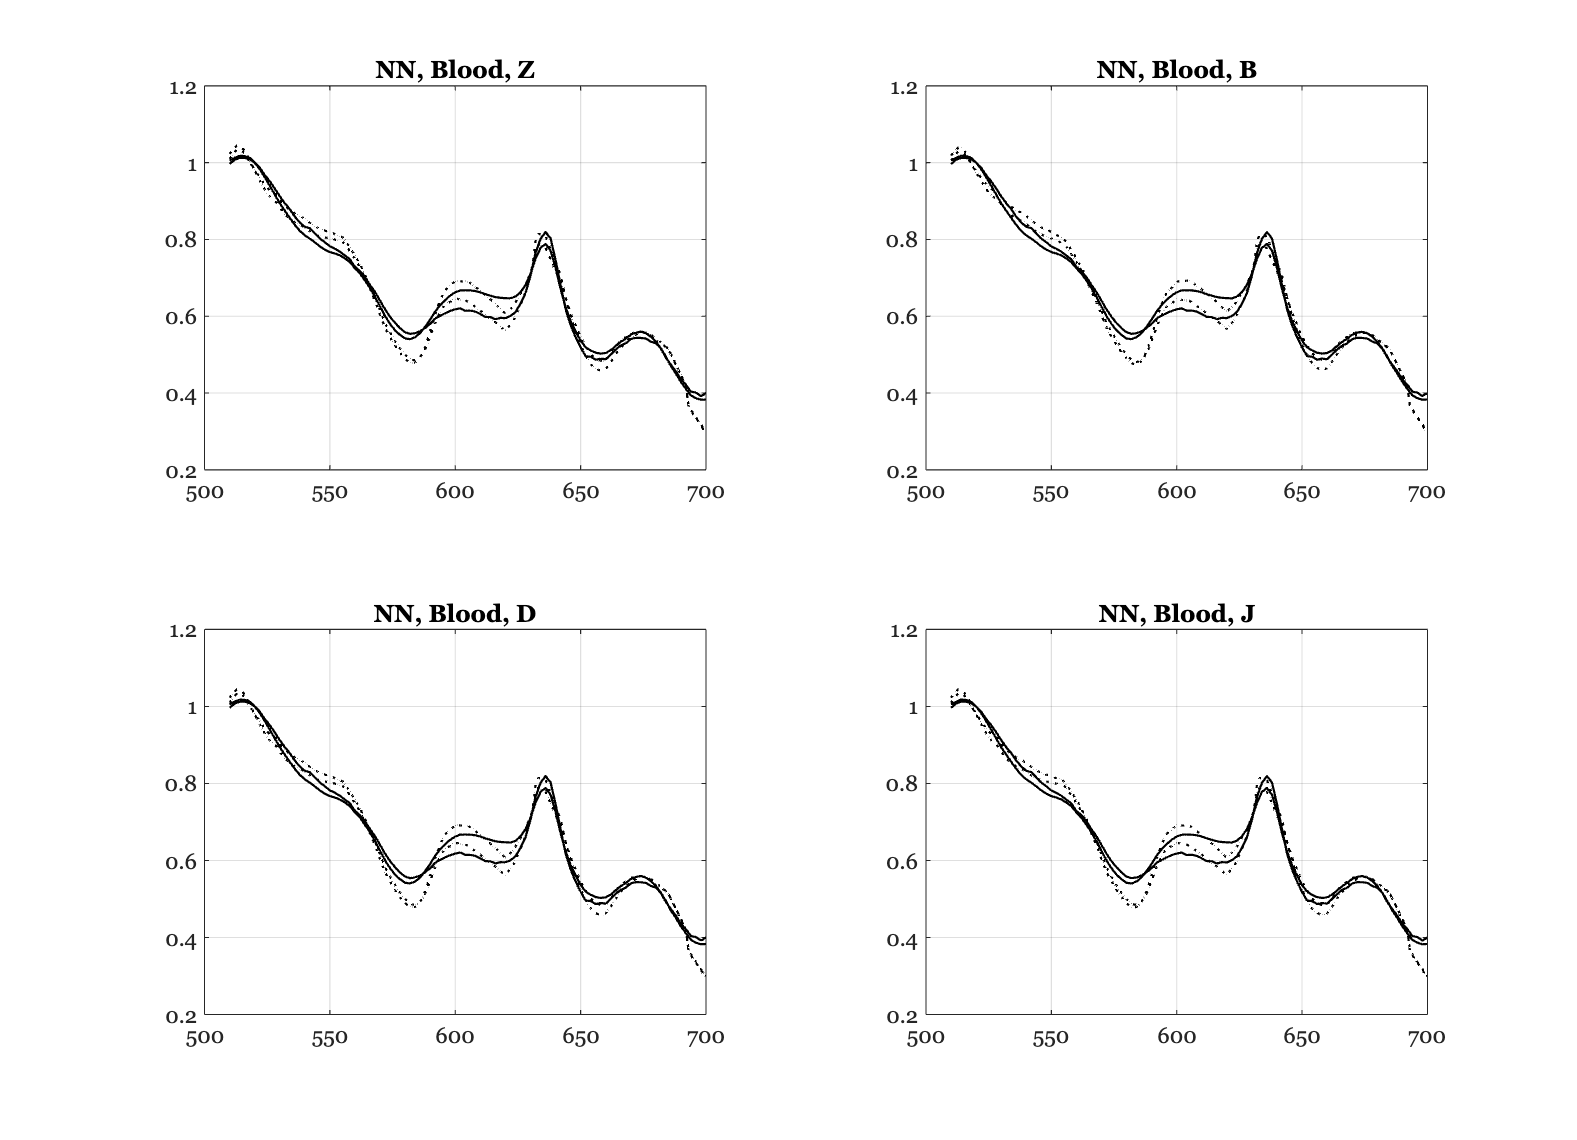

Subject Z
   16.6661   14.1502
    0.3519    0.5043
    0.7650    0.7665
    0.2588    0.3399
    0.2072    0.2359

Subject B
   16.8149   14.2742
    0.6254    0.7367
    0.7384    0.7440
    0.2508    0.3332
    0.2029    0.2322

Subject D
   16.6661   14.1502
    0.3519    0.5043
    0.7650    0.7665
    0.2588    0.3399
    0.2072    0.2359

Subject J
   16.6661   14.1502
    0.3519    0.5043
    0.7650    0.7665
    0.2588    0.3399
    0.2072    0.2359



ieFigure;
tiledlayout(2,2);
for ii=1:numel(subjects)
    wgtsNN = zeros(size(fluorophoresB,2),size(tongueData,2));

    oxyblood.opticalDensity = ods(ii);
    fluorophores = oeApplyBlood(fluorophoresB,fluorophoreNamesB,oxyblood);
    for dd = 1:size(tongueData,2)
        wgtsNN(:,dd) = lsqnonneg(fluorophores,tongueData(:,dd));
    end

    nexttile
    plot(wave,tongueData,'k-',wave,fluorophores*wgtsNN,'k:');
    grid on; title(sprintf('NN, Blood, %s',subjects{ii}));
    fprintf('Subject %s\n',subjects{ii}); disp(wgtsNN);
end